# Sistemi LTI: misura di risposta al chirp (sinusoide con sweep in frequenza) 

## Generazione di sinusoide con sweep lineare

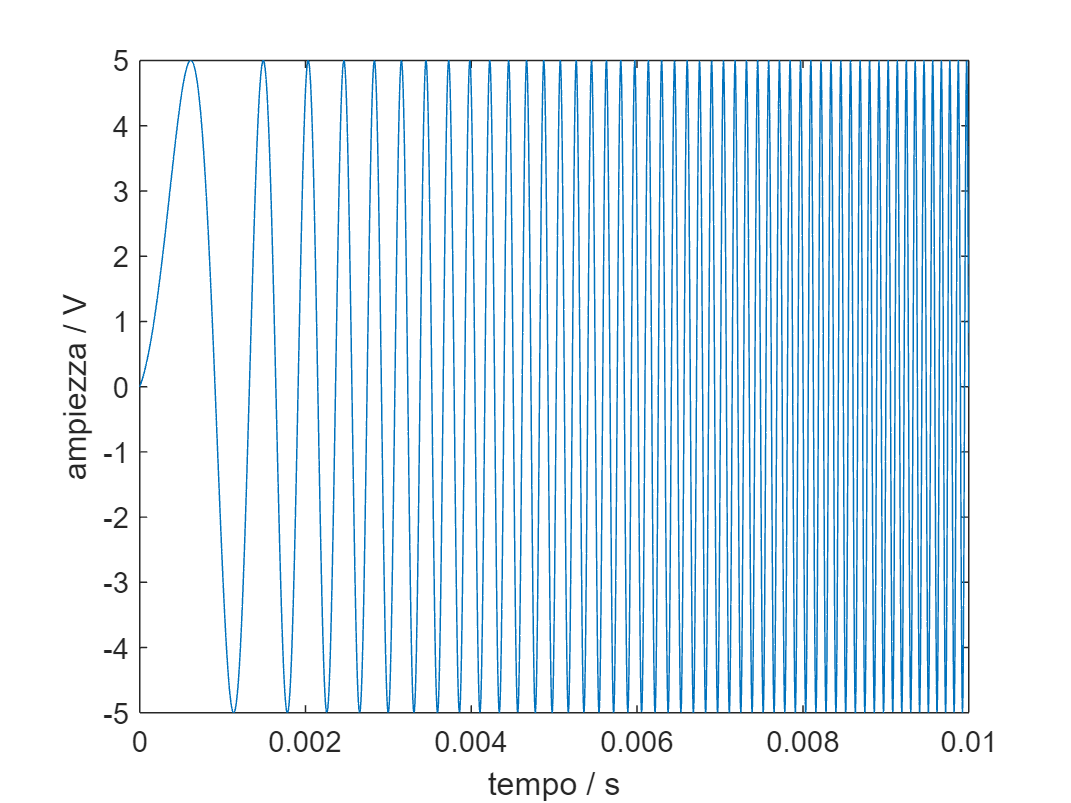


$$f=f_0 +\left(f_1 -f_0 \right)\frac{t}{t_{\textrm{sw}} }$$


% Dati
% V0 % ampiezza / V
% f0 % frequenza iniziale / Hz
% f1 % frequenza finale / Hz
% tsw % tempo di sweep / s
% N % numero di campioni

% Domande
% t = istanti di tempo (vettore colonna)
% f = frequenze corrispondenti a t
% phi = % fasi corrispondenti
% x = chirp lineare


% Codice iniziale
clear
V0 = 5

V0 = 5

f0 = 100

f0 = 100

f1 = 10000

f1 = 10000

tsw = 1e-2

tsw = 0.0100

N = 1e6

N = 1000000

### Soluzione

Istanti di tempo equispaziati

Td = tsw;
Ts = Td/N;
n = (0:N-1)';
t = n*Ts;

Frequenze

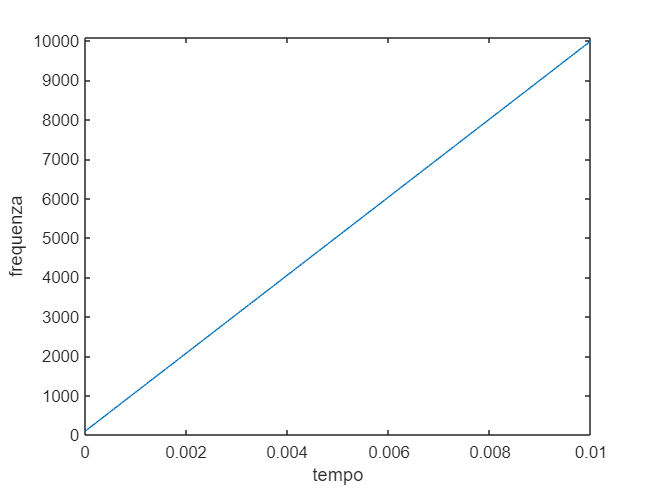

f = f0 + (f1 - f0)*t/tsw;
plot(t,f)
ylim([0,f1+f0])
xlabel('tempo')
ylabel('frequenza')

Fasi


$$\varphi \left(t\right)=2\pi \;\int_0^t f\left(t\right)\textrm{dt}$$


dt = Ts

dt = 1.0000e-08

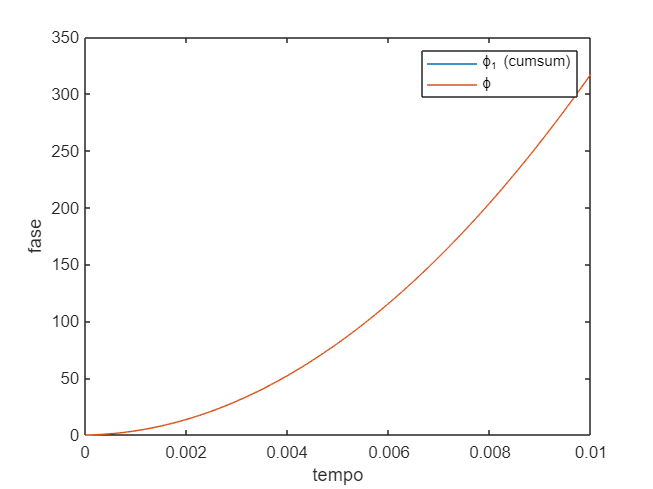

phi1 = 2*pi*cumsum(f)*dt;
phi = 2*pi*(f0*t + (f1-f0)/tsw*t.^2/2);
plot(t,phi1,t,phi)
xlabel('tempo')
ylabel('fase')
legend('\phi_1 (cumsum)', '\phi')

Segnale

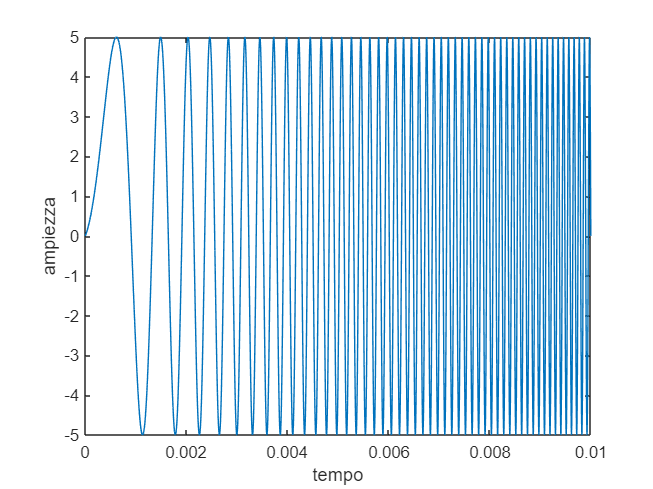

x = V0*sin(phi);
plot(t,x)
xlabel('tempo')
ylabel('ampiezza')

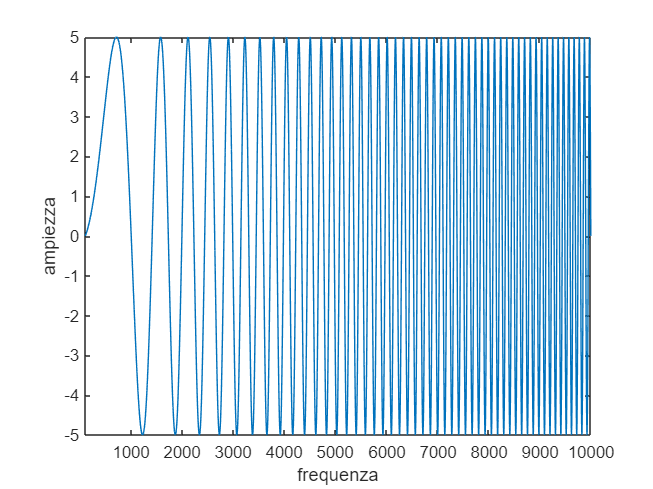

plot(f,x)
xlim([f0,f1])
xlabel('frequenza')
ylabel('ampiezza')

## Simulazione di risposta di circuito RC a sweep lineare


$$f=f_0 +\left(f_1 -f_0 \right)\frac{t}{t_{\textrm{sw}} }\Rightarrow \frac{t}{t_{\textrm{sw}} }=\frac{f-f_0 }{f_1 -f_0 }$$


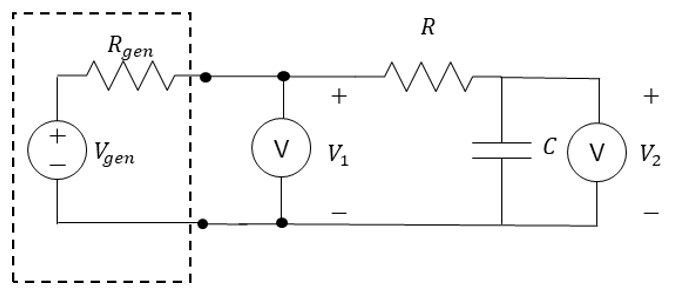

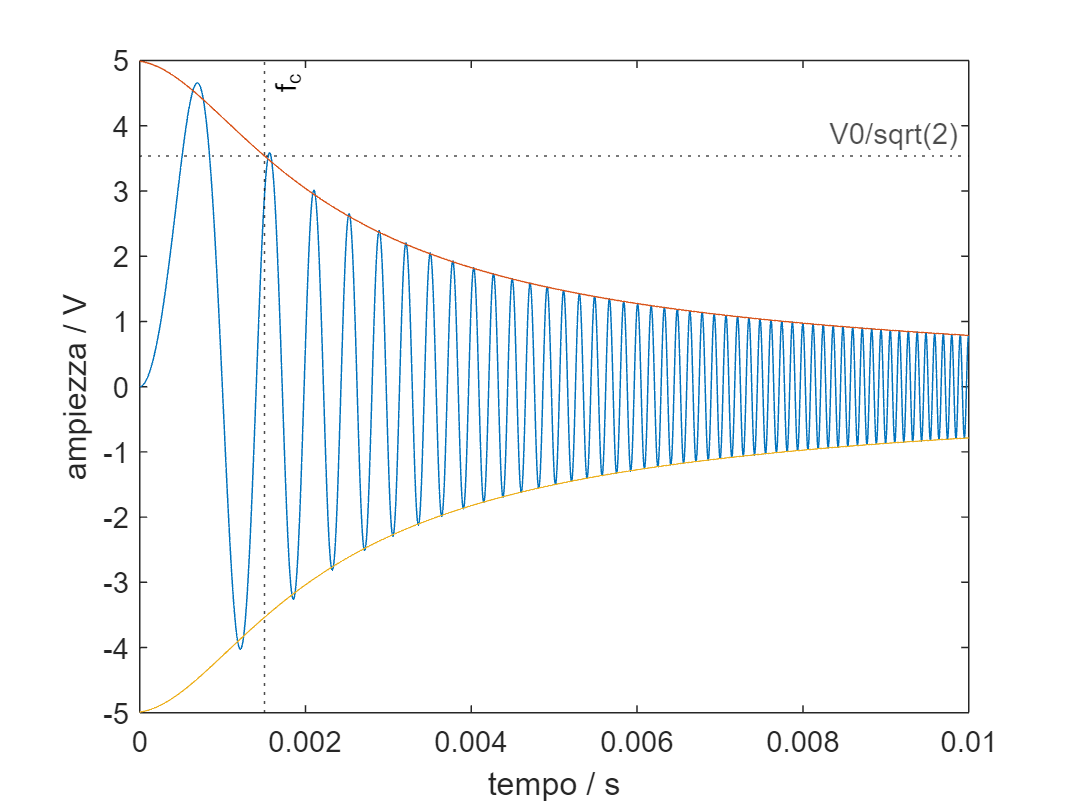

% Si simuli la risposta a sinusoide con sweep lineare per il circuito in figura.
% Si produca un grafico come quello in figura, con evidenziata la risposta
% di ampiezza e l'istante corrispondente alla frequenza di taglio del sistema

% Dati
% R = % resistenza / ohm
% C = % capacità / F
% s = tf('s') % variabile della trasformata di Laplace
% t = istanti di tempo (vettore colonna)
% x = segnale di ingresso, chirp lineare

% Domande
% Rgen = resistenza del generatore
% tau = costante di tempo del sistema, ai fini della risposta allo sweep
% fc = frequenza di taglio del sistema, ai fini della risposta allo sweep
% H_tf = funzione di trasferimento
% y = risposta al segnale x
% f = frequenze corrispondenti a t
% H = risposta di ampiezza del sistema alle frequenze f corrispondenti a t
% tc = istante corrispondente alla frequenza di taglio fc del sistema

% Codice iniziale
R = 50; % resistenza
C = 1e-6; % capacità
s = tf('s') % variabile della trasformata di Laplace

s =
 
  s
 
Continuous-time transfer function.



### Soluzione

Funzione di trasferimento

Rgen = 50

Rgen = 50

R1 = R + Rgen

R1 = 100

tau = R1*C

tau = 1.0000e-04

fc = 1/(2*pi*tau)

fc = 1.5915e+03

H_tf = 1/(1+s*tau)

H_tf =
 
       1
  ------------
  0.0001 s + 1
 
Continuous-time transfer function.



Risposta a sweep lineare

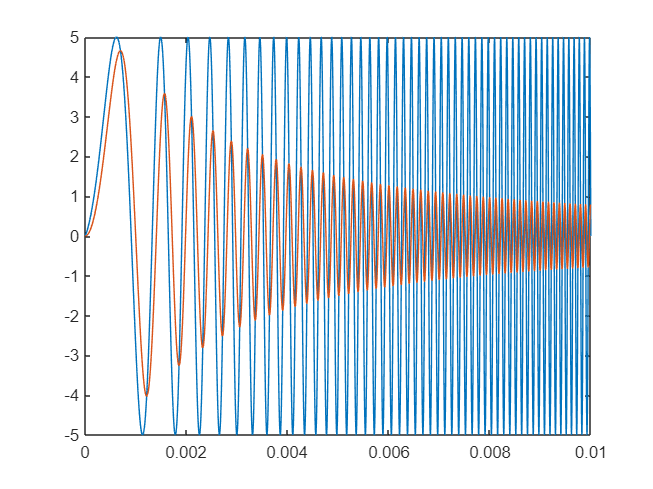

y = lsim(H_tf,x,t);
plot(t,x,t,y)

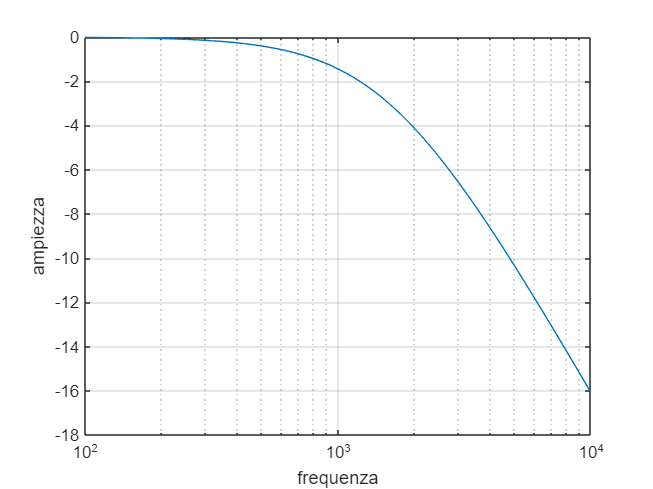

f = f0+ (f1-f0).*t/tsw;
H = 1./sqrt(1+(f/fc).^2);
HdB = 20*log10(H);
semilogx(f,HdB),grid
xlabel('frequenza')
ylabel('ampiezza')


plot(t,y,t,V0*H,t,-V0*H)
yline(V0/sqrt(2),':k','V0/sqrt(2)')
tc = tsw*(fc-f0)/(f1-f0)

tc = 0.0015

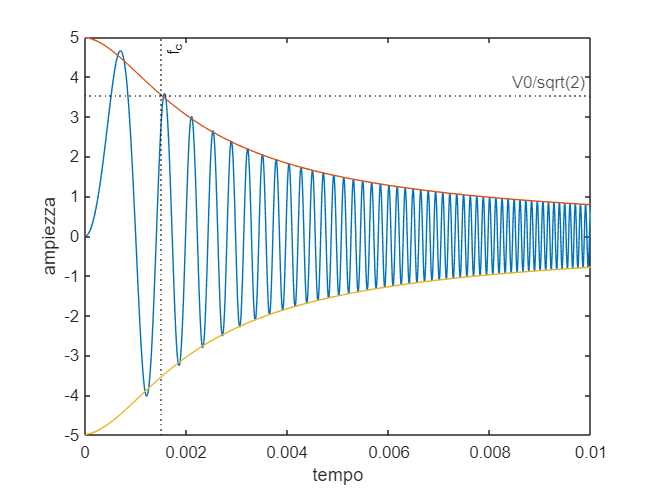

xline(tc, ':k','f_c')
xlabel('tempo')
ylabel('ampiezza')

## Generazione di sinusoide con sweep logaritmico

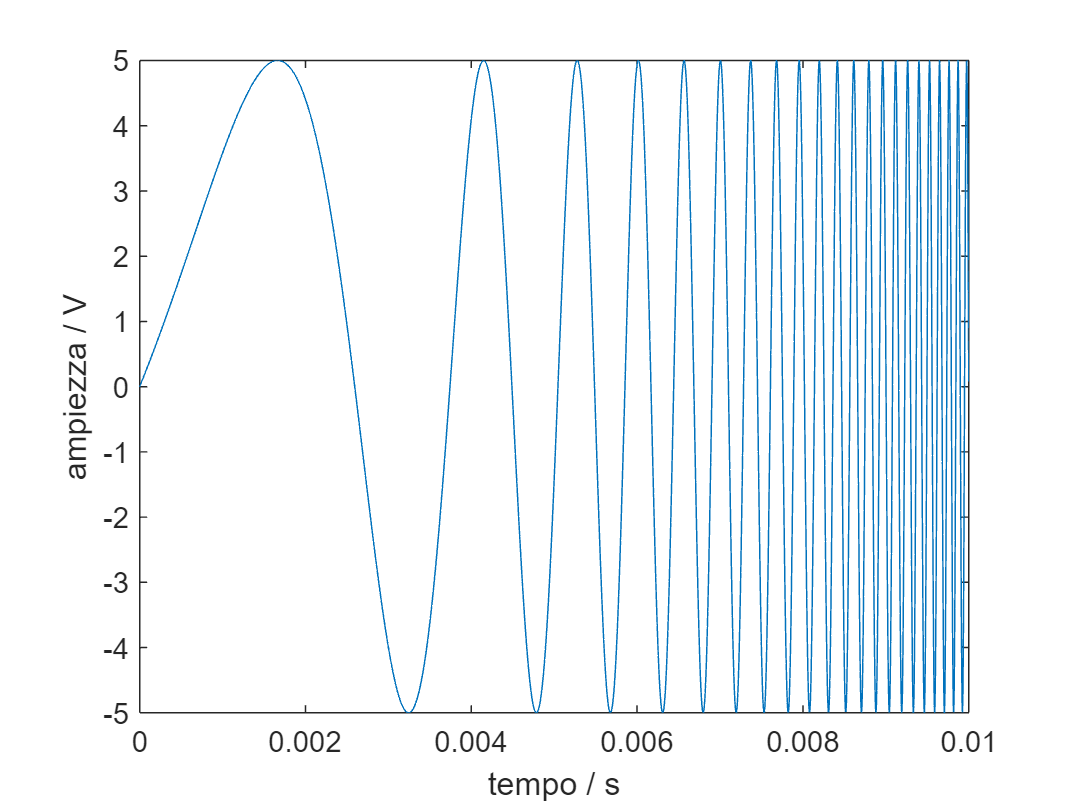


$$f=f_0 +\left(f_1 -f_0 \right)\frac{t}{t_{\textrm{sw}} }\;\to f=f_0 {\left(\frac{f_1 }{f_0 }\right)}^{\frac{t}{t_{\textrm{sw}} }}$$


% Dati
% V0 = % ampiezza / V
% f0 = % frequenza iniziale / Hz
% f1 = % frequenza finale / Hz
% tsw = % tempo di sweep / s
% N = % numero di campioni

% Domande
% t = istanti di tempo (vettore colonna)
% f = frequenze corrispondenti a t
% phi = % fasi corrispondenti
% x = chirp logaritmico


% Codice iniziale
clear
V0 = 5

V0 = 5

f0 = 100

f0 = 100

f1 = 10000

f1 = 10000

tsw = 1e-2

tsw = 0.0100

N = 1e6

N = 1000000

### Soluzione

Istanti di tempo equispaziati

Td = tsw;
Ts = Td/N;
n = (0:N-1)';
t = n*Ts;

Frequenze

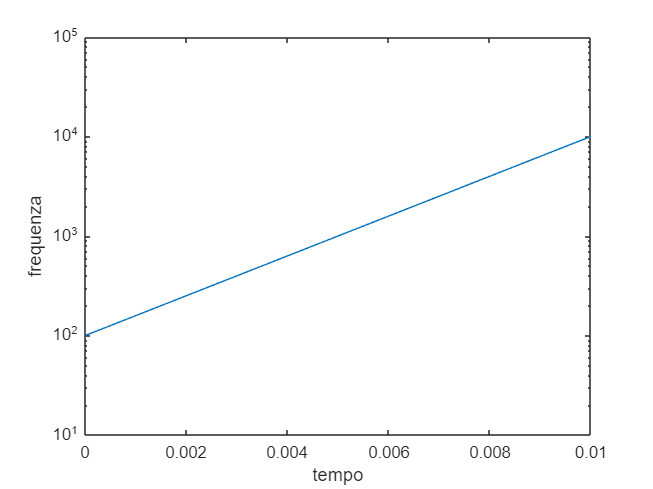

f = f0*(f1/f0).^(t/tsw);
semilogy(t,f)
ylim([f0/10,f1*10])
xlabel('tempo')
ylabel('frequenza')

Fasi


$$\varphi \left(t\right)=2\pi \;\int_0^t f\left(t\right)\textrm{dt}$$


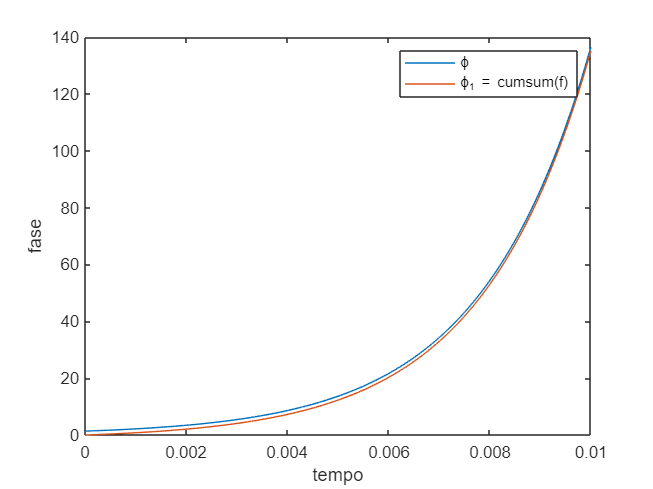

dt = Ts;
phi = 2*pi*(f0*(f1/f0).^(t/tsw).*tsw/log(f1/f0));
phi1 = 2*pi*cumsum(f)*dt; %vantaggio: valore iniziale = 0
plot(t,phi,t,phi1)
xlabel('tempo')
ylabel('fase')
legend('\phi','\phi_1 = cumsum(f)')

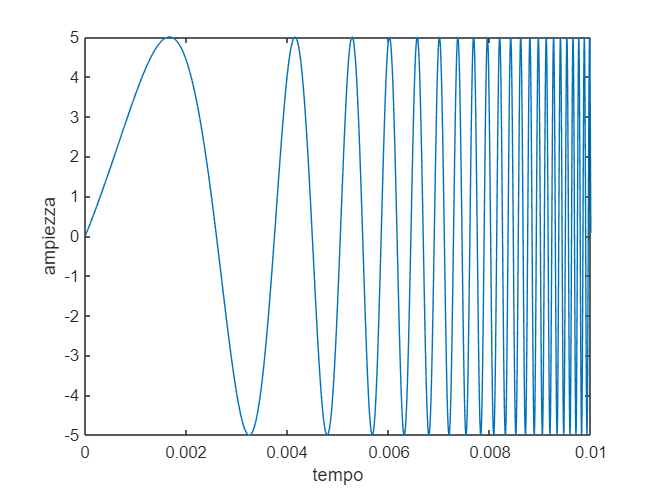


x = V0*sin(phi1);
plot(t,x)
xlabel('tempo')
ylabel('ampiezza')

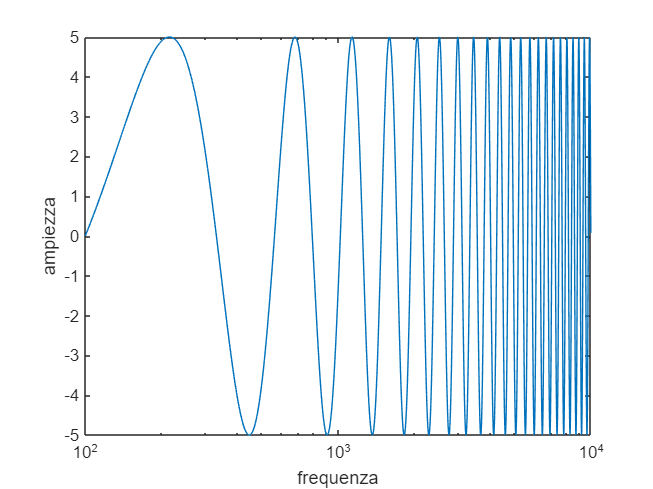


semilogx(f,x)
xlabel('frequenza')
ylabel('ampiezza')

## Simulazione di risposta di circuito RC a sweep logaritmico


$$f=f_0 {\left(\frac{f_1 }{f_0 }\right)}^{\frac{t}{t_{\textrm{sw}} }} \Rightarrow \frac{t}{t_{\textrm{sw}} }=\frac{\log \left(\frac{f}{f_0 }\right)}{\log \left(\frac{f_1 }{f_0 }\right)}=\frac{\log \;f-\log \;f_0 }{\log \;f_1 -\log \;f_0 }$$


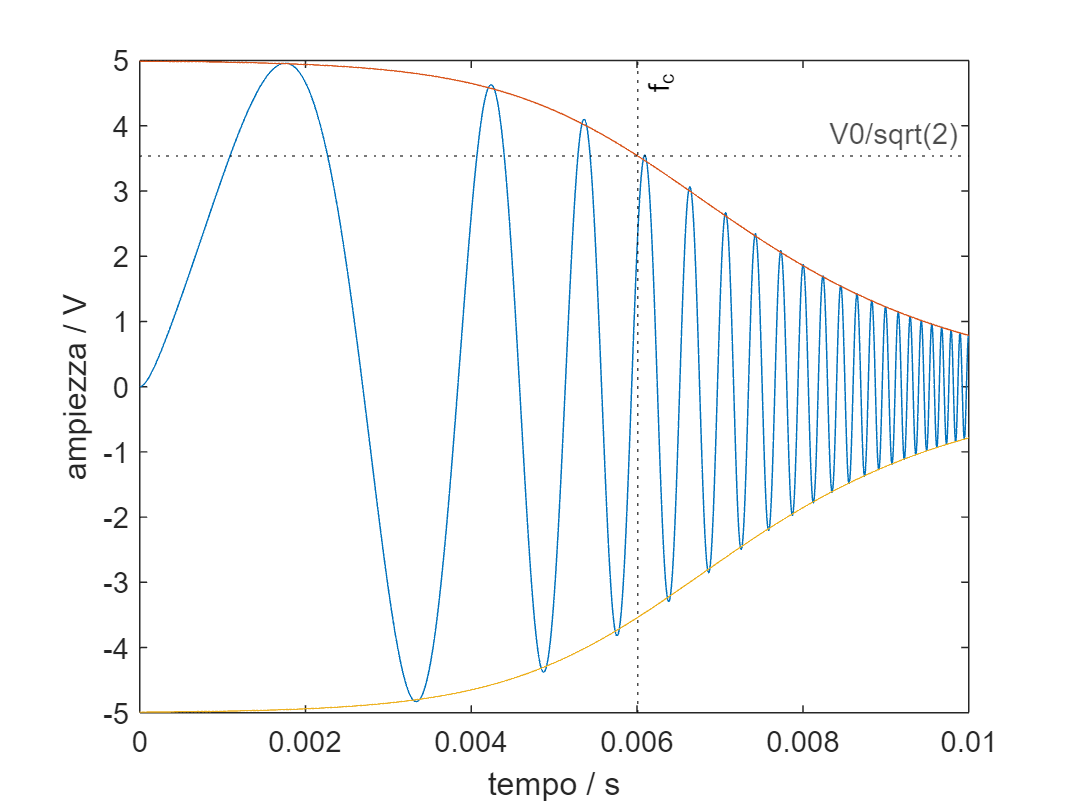

% Si simuli la risposta a sinusoide con sweep logaritmico per il circuito in figura
% Si produca un grafico come quello in figura, con evidenziata la risposta di
% ampiezza e l'istante corrispondente alla frequenza di taglio del sistema

% Dati
% R = % resistenza / ohm
% C = % capacità / F
% s = tf('s') % variabile della trasformata di Laplace
% t = istanti di tempo (vettore colonna)
% x = segnale di ingresso, chirp lineare

% Domande
% Rgen = resistenza del generatore
% tau = costante di tempo del sistema
% fc = frequenza di taglio del sistema
% H_tf = funzione di trasferimento
% y = risposta al segnale x
% f = frequenze corrispondenti a t
% H = risposta di ampiezza del sistema alle frequenze f corrispondenti a t
% tc = istante corrispondente alla frequenza di taglio del sistema

% Codice iniziale
R = 50; % resistenza
C = 1e-6; % capacità
s = tf('s') % variabile della trasformata di Laplace

s =
 
  s
 
Continuous-time transfer function.



### Soluzione

Funzione di trasferimento

Rgen = 50

Rgen = 50

R1 = R+Rgen

R1 = 100

tau = R1*C

tau = 1.0000e-04

fc = 1/(2*pi*tau)

fc = 1.5915e+03

H_tf = 1/(1+s*tau)

H_tf =
 
       1
  ------------
  0.0001 s + 1
 
Continuous-time transfer function.



Risposta a sweep logaritmico

y = lsim(H_tf,x,t)

y =    -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


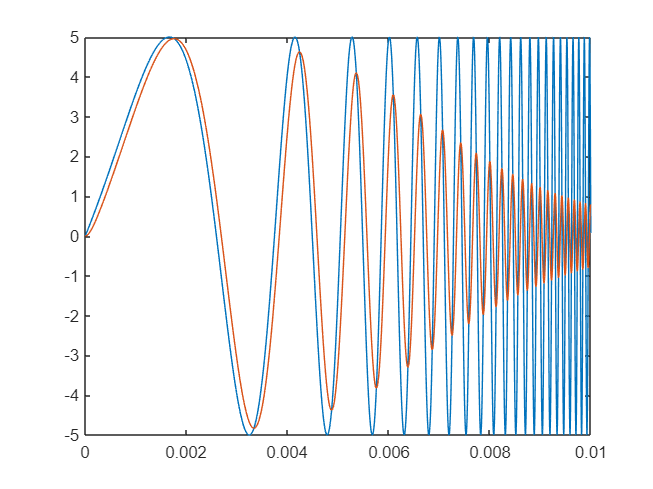

plot(t,x,t,y)

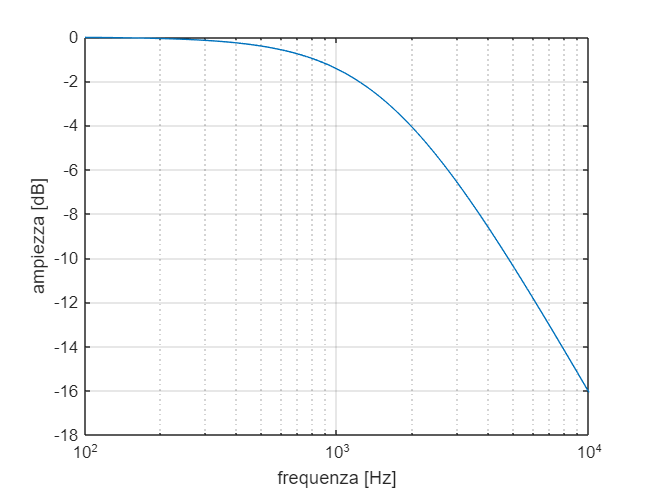

f = f0*(f1/f0).^(t/tsw);
H = 1./sqrt(1+(f/fc).^2);
HdB = 20*log10(H);
semilogx(f,HdB),grid
xlabel('frequenza [Hz]')
ylabel('ampiezza [dB]')


tc = tsw*log(fc/f0)/log(f1/f0)

tc = 0.0060

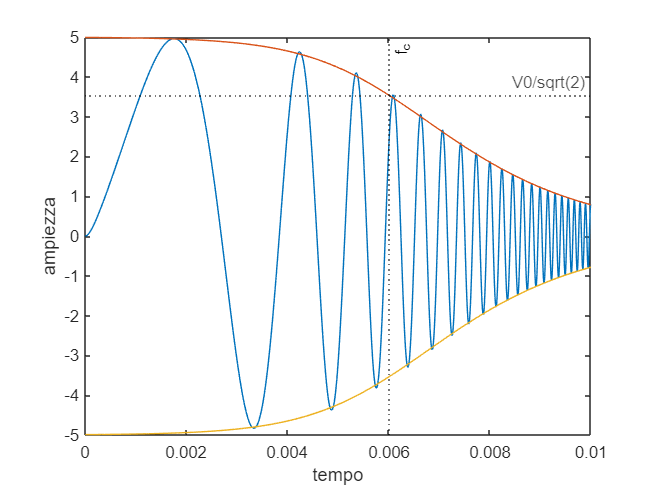

plot(t,y,t,V0*H,t,-V0*H)
yline(V0/sqrt(2), ':k','V0/sqrt(2)')
xline(tc, ':k', 'f_c')
xlabel('tempo')
ylabel('ampiezza')

## Calcolo di funzione di trasferimento di circuito RLC

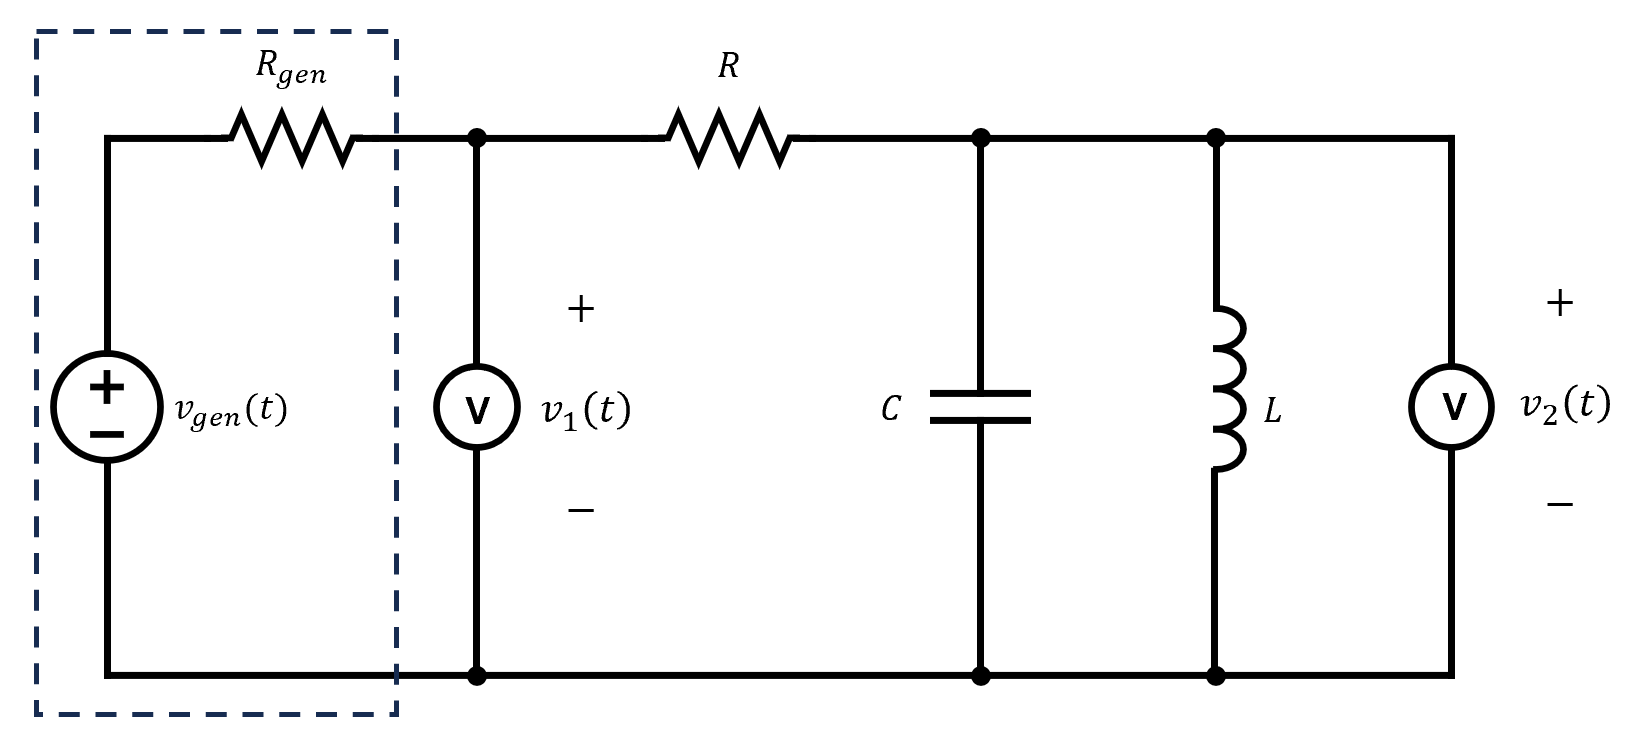

% Scrivere la funzione di trasferimento H_ft = V2/Vgen del circuito in figura.

% Dati
% R % resistenza / ohm
% C % capacità / F
% L % induttanza / H
% s = tf('s') % varibile della trasformata di Laplace

% Domande
% H_tf % funzione di trasferimento
% fR % frequenza di risonanza / Hz

% Codice iniziale
clear
R = 50

R = 50

C = 1e-6

C = 1.0000e-06

L = 1e-3

L = 1.0000e-03

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



### Soluzione

% Risposta da calcoli manuali
Rgen = 50

Rgen = 50

R1 = R+Rgen

R1 = 100

tau = L/R1

tau = 1.0000e-05

w0 = sqrt(L*C)

w0 = 3.1623e-05

H_tf = tau*s/(1+s*tau+s^2*w0^2)

H_tf =
 
          1e-05 s
  -----------------------
  1e-09 s^2 + 1e-05 s + 1
 
Continuous-time transfer function.



% Risposta da calcoli in Matlab
zC = 1/(s*C) %impedenza della capacità

zC =
 
     1
  -------
  1e-06 s
 
Continuous-time transfer function.



zL = s*L %impedenza dell'induttanza

zL =
 
  0.001 s
 
Continuous-time transfer function.



zLC = zC*zL/(zC+zL) %impedenza del parallelo LC

zLC =
 
       1e-09 s^2
  -------------------
  1e-15 s^3 + 1e-06 s
 
Continuous-time transfer function.



H1_tf = zLC/(R1+zLC) %partitore di tensione

H1_tf =
 
                    1e-24 s^5 + 1e-15 s^3
  ---------------------------------------------------------
  1e-28 s^6 + 1e-24 s^5 + 2e-19 s^4 + 1e-15 s^3 + 1e-10 s^2
 
Continuous-time transfer function.



% Verifica
H_tf = minreal(H_tf)

H_tf =
 
        10000 s
  -------------------
  s^2 + 1e04 s + 1e09
 
Continuous-time transfer function.



H1_tf = minreal(H1_tf)

H1_tf =
 
        10000 s
  -------------------
  s^2 + 1e04 s + 1e09
 
Continuous-time transfer function.



% Frequenza di risonanza
fR = w0/(2*pi)

fR = 5.0329e-06

## Circuito RLC (con Symbolic Toolbox)

Soluzione: $H\left(s\right)=\frac{L\,s}{C\,L\,R_1 \,s^2 +L\,s+R_1 }$

% Derivare la funzione di trasferimento del circuito precedente utilizzando il Symbolic Toolbox

% Dati (sono tutti variabili simboliche)
% R1 % resistenza R + Rgen
% C % capacità
% L % induttanza
% s % variabile della trasformata di Laplace

% Domande
% H_sym % funzione di trasferimento


clear
syms R1 C L s real

### Soluzione

zC = 1/(s*C) %impedenza della capacità

$$zC = \frac{1}{C\,s}$$

zL = s*L %impedenza dell'induttanza

$$zL = L\,s$$

zLC = zC*zL/(zC+zL) %impedenza del parallelo LC

$$zLC = \frac{L}{C\,\left(L\,s+\frac{1}{C\,s}\right)}$$

H_sym = simplify(zLC/(R1+zLC)) %formula del partitore di tensione

$$H\_sym = \frac{L\,s}{C\,L\,R_{1}\,s^{2}+L\,s+R_{1}}$$

## Simulazione di risposta di circuito RLC a sweep lineare

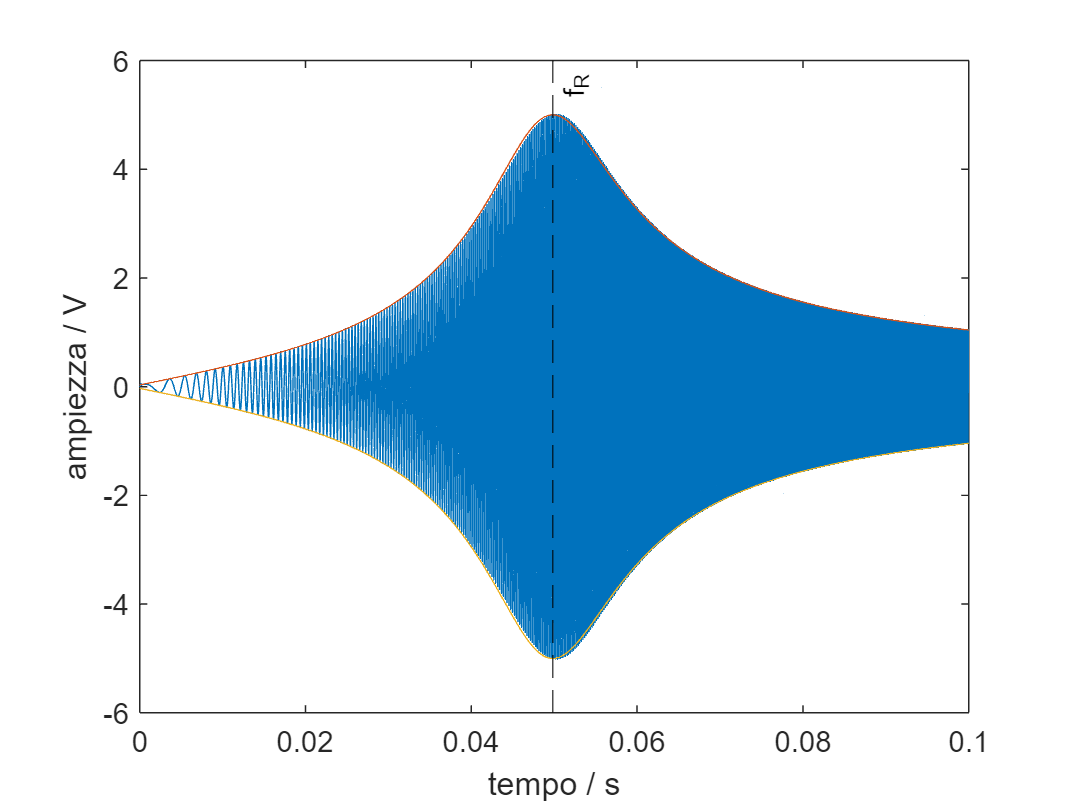

% Si simuli la risposta a sinusoide con sweep lineare per il circuito RLC
% Si produca un grafico come quello in figura, con evidenziato l'istante 
% corrispondente alla frequenza di risonanza del sistema

% Dati
% R = % resistenza / ohm
% C = % capacità / F
% L = % induttanza / H
% s = tf('s') % variabile della trasformata di Laplace
% t = istanti di tempo (vettore colonna)
% x = segnale di ingresso, chirp lineare

% Domande
% Rgen = resistenza del generatore
% H_tf = funzione di trasferimento
% y = risposta al segnale x
% f = frequenze corrispondenti a t
% H = risposta di ampiezza del sistema alle frequenze f corrispondenti a t
% tR = istante corrispondente alla frequenza di risonanza


% Codice iniziale
clear
V0 = 5

V0 = 5

f0 = 100

f0 = 100

f1 = 10000

f1 = 10000

tsw = 1e-1 % provare anche con 1e-2

tsw = 0.1000

N = 1e6

N = 1000000

Td = tsw;
Ts = Td/N;
n = (0:N-1)';
t = n*Ts;
phi = 2*pi*(f0*t + (f1-f0)/tsw*t.^2/2);
x = V0*sin(phi);

R = 50; % resistenza
C = 1000e-9; % capacità
L = 1e-3; % induttanza
s = tf('s') % variabile della trasformata di Laplace

s =
 
  s
 
Continuous-time transfer function.



### Soluzione

Rgen = 50

Rgen = 50

R1 = R+Rgen

R1 = 100

tau = L/R1

tau = 1.0000e-05

w0 = 1/sqrt(L*C)

w0 = 3.1623e+04

H_tf = tau*s/(1+s*tau+s^2/w0^2)

H_tf =
 
        10000 s
  --------------------
  s^2 + 10000 s + 1e09
 
Continuous-time transfer function.




y = lsim(H_tf,x,t)

y =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


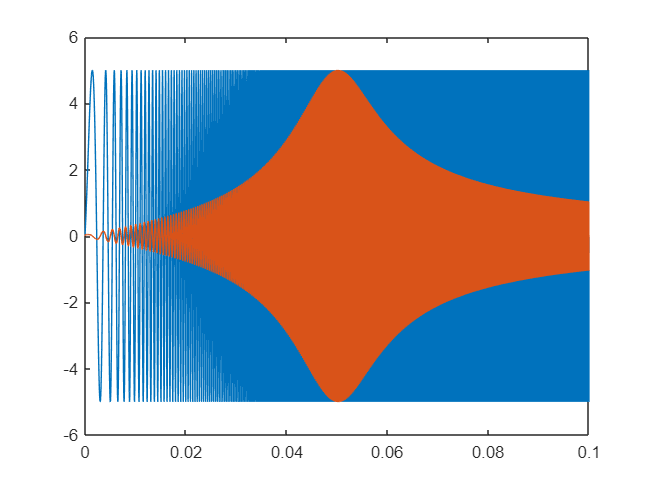

plot(t,x,t,y)

f = f0 + (f1-f0)*t/tsw

f = 	1.0e+03 *

    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1001
    0.1001
    0.1001
    0.1001



s1 = 1j*2*pi*f; % variabile ausiliaria per calcolare la FRF
H_dot = tau*s1./(1+s1*tau+s1.^2/w0^2) %FRF complessa

H_dot =    0.0000 + 0.0063i
   0.0000 + 0.0063i
   0.0000 + 0.0063i
   0.0000 + 0.0063i
   0.0000 + 0.0063i
   0.0000 + 0.0063i
   0.0000 + 0.0063i
   0.0000 + 0.0063i
   0.0000 + 0.0063i
   0.0000 + 0.0063i


H = abs(H_dot); %risposta di ampiezza

fR = w0/(2*pi); %frequenza di risonanza
tR = tsw*(fR-f0)/(f1-f0) %istante corrispondente alla frequenza di risonanza

tR = 0.0498

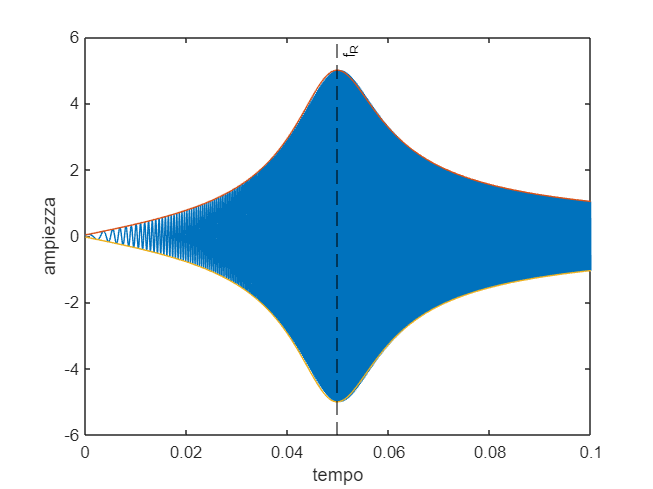


plot(t,y,t,V0*H,t,-V0*H)
xline(tR,'--k','f_R')
xlabel('tempo')
ylabel('ampiezza')

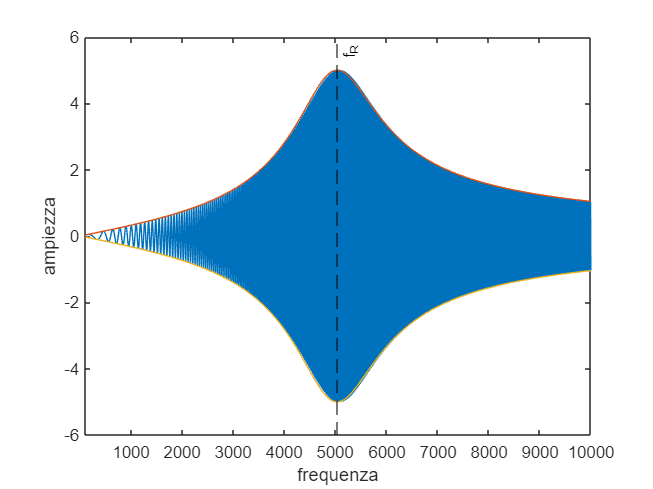


plot(f,y,f,V0*H,f,-V0*H)
xlim([f0,f1])
xline(fR,'--k','f_R')
xlabel('frequenza')
ylabel('ampiezza')